# Loading NIR Spectra

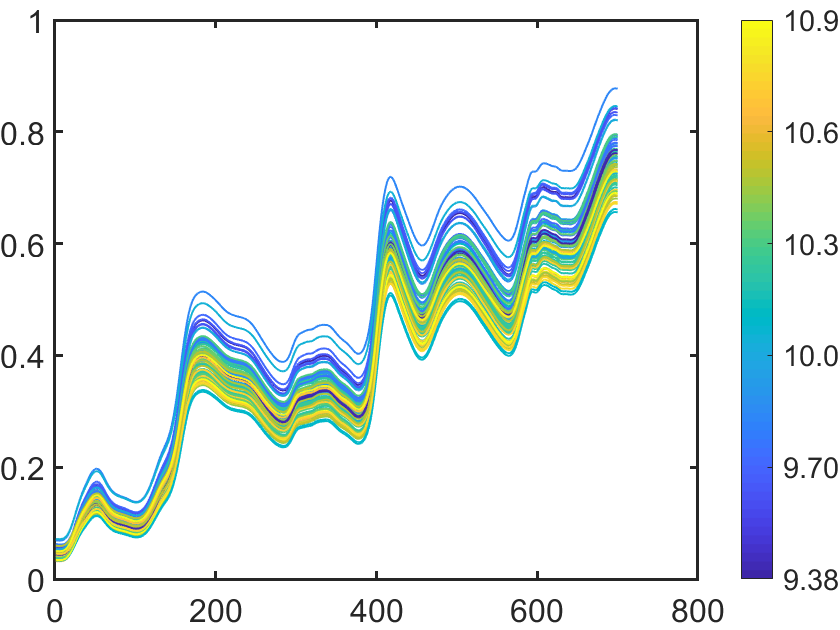

clear;
load corn
X = m5spec.data;
y = propvals.data(:,1); %moisture
%plot(X');
%SCIPlot
plotSpectra(X,y);

# Noise Removal

**Moving average window**

A simple smoothing method is to replace the value of each point i in the spectrum by the average of the point values over a window of width w, centered on point i. The window is moved along the spectrum, hence the name moving average window or boxcar filter.

To accelater the computing, it is worthy to use matrix to replace the 'conv'

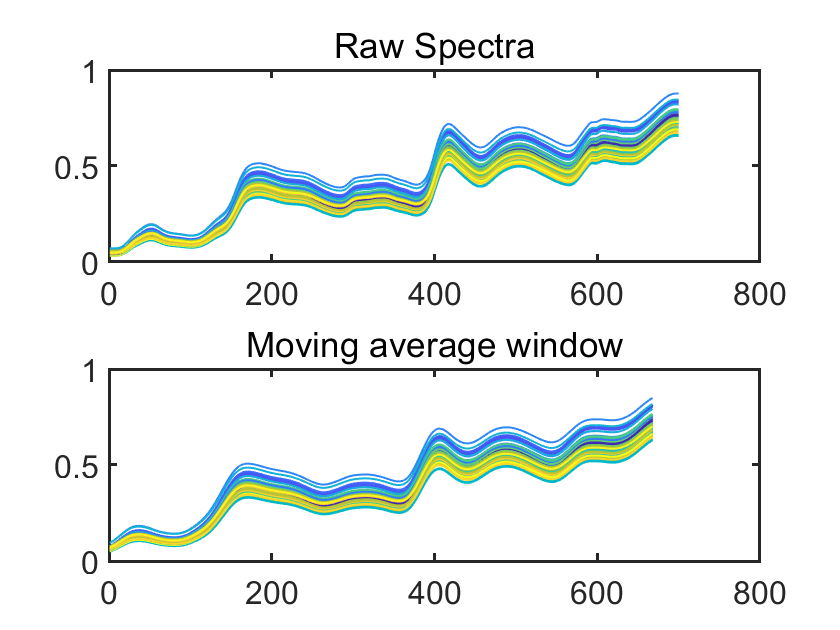

ws = 33;
tmp = [];
filter1 = [ones(1,ws)]/ws; 
for i = 1:1:size(X,1)
    tmp(i,:) = conv(X(i,:),filter1,'valid');
end
figure;
subplot(2,1,1);
plotSpectra(X,y);
title("Raw Spectra");
colorbar('off');
subplot(2,1,2);
plotSpectra(tmp,y);
title("Moving average window");
colorbar('off');

**Savitsky-Golay method**

The [Savitzky-Golay algorithm](http://adsabs.harvard.edu/abs/1964AnaCh..36.1627S) is based on a moving window that fit a polynomial curve of fixed degree to the spectral data. It is assumed that the fitted values are a better estimate than the measured ones and therefore that some noise is being removed in the process. 

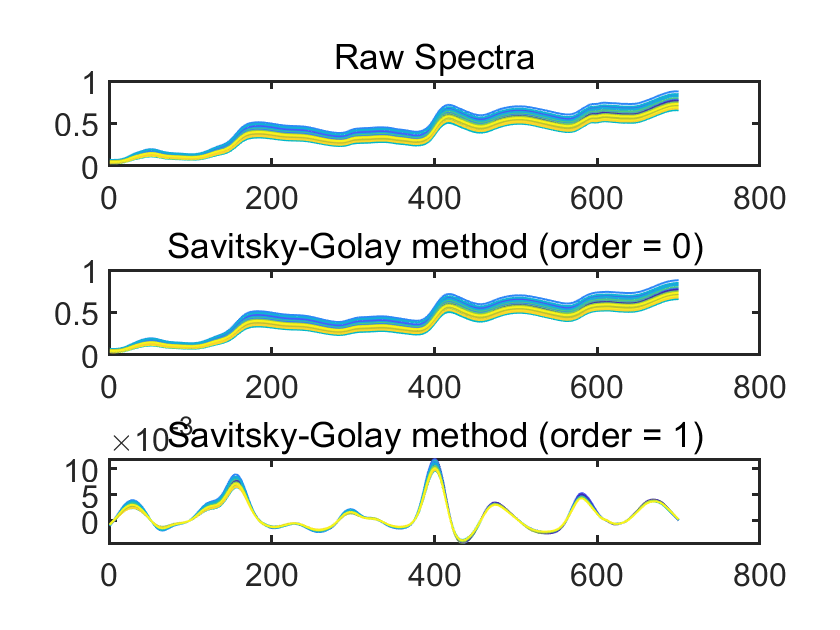

tmp1 = [];
tmp2= [];
for i = 1:1:size(X,1)
    tmp1(i,:) = savgol(X(i,:),33,2,0); 
    tmp2(i,:) = savgol(X(i,:),33,2,1); 
end
figure;
subplot(3,1,1);
plotSpectra(X,y);
title("Raw Spectra");
colorbar('off');
subplot(3,1,2);
plotSpectra(tmp1,y);
title("Savitsky-Golay method (order = 0)");
colorbar('off');
subplot(3,1,3);
plotSpectra(tmp2,y);
title("Savitsky-Golay method (order = 1)");
colorbar('off');